## **Throughput equation**

function T_id=Throughput(lambda,P_iD)

end

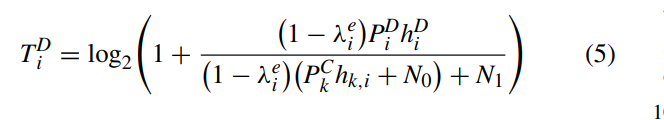

## **Prematching Algorithm**

function [SiD,InfD,EhaD] = Prematch(D,C,Pkc,Pth1,Pmax,TminD)
% set the channel responses of D2D link and channel responses from D2D link
% and CUE link
syms hD h_interference_D2D_CUE
SiD=C;
%Non-EH D2D links
InfD=[];
%SWIPT-Eanbled communication system
EhaD=[];
for i=1:size(D,2)
    for k=1:size(C,2)
        %\lamda ie
        lambda_min=Pth1/(Pmax*hD(i)+Pkc* h_interference_D2D_CUE(k,i)+N0);
        Tid_max=log2(1+(Pmax*hD(i))/(Pkc*h_interference_D2D_CUE(k,i)+N0+(N1)/1-lambda_min));
        %compare the minimum power splitting ratio and maximum
        %Throughput,if both of the requiremnts can not be met, then the k
        %will be removed from the selection set.
        if lambda_min>1 || Tid_max<TminD
            SiD(SiD==k)=[];
        end 
    end
    %After the CUE set was scanned, then check if the selection set is
    %empty
    if isempty(SiD)==1
        InfD(end+1)=i;
    end
    
    if isempty(SiD)~=1
        EhaD(end+1)=i;
    end
end
            
        
end

## Outer loop Algorithm

function [Pid_optimal,lambda_optimal,EE_optimal]=Outer(EhaD,SiD,lambda,P_ijD,EE_ijD)
%first of all, we need to search the whole SWIPT-Enabled D2D communication
%system, then search for the partner selection set obtained by the
%pre-matching algorithm. Then we set Nmax segments first then search them,
%for each segment, we need to find the maxmimum Energy Efficiency of each
%segment and the j value at which Energy efficiecny reaches its maximum
%value, then update the optimal value of J, transmission power PiD_optimal,
%power plitting ratio lambda_optimal, and ofcourse the energy efficiency EE_optimal
for i =1:size(Ehad,2)
    for k=1:size(SiD,2)
        for j=1:Nmax
            [argvalue,argmax]=max(EE_ijD(i:j));
            j_optimal=argmax;
            Pid_optimal=P_ijD(i,j_optimal);
            lambda_optimal=lambda(i,j_optimal);
            EE_optimal=EE_ijD(i,j_optimal);
        end
    end
end
end


## Inner loop Algorithm

First of all we need to determine the maximum segments before we get,started with the algorithm, according to the piecewise function of EH model in the picuture below. So to get the maximum number of segments, we need to first figure out which segment of Pth which is the threshold power of PiR belongs to, by using the equation below, we can get the maximum value of the received power PiR then we need to compare it to the piecewise model and figureout the which segment it blongs to then we can get the maximum number of segemnts.

So first use the euqation to obtain the mamimum PiR:

1. Scan the Enabled SWIPT D2D links, set each segemnt's maximum value of received power to the array.

2. Then find the ponint where the received  power reches the maximum value among each segemnt's maximum value.

3. Then the corresponding maximum value among all of these "maximum value" will be used to compare to the piecewise model by traversing through the whole threshold power array and the maximum segments will be found.

Then we can start to implement the algorithm with my obtained maximum value of segments:Nmax

function [lambda_ij,P_ij,EE_ij]=Inner(EhaD,S_iD)
syms Initial_QiD Initial_P_iD P_iR hD Pmax P_kc Pth h_k N0 P_th K_intercept B_intercept optimal_lambda
syms a1 a2 a3 K G H J
syms m1 m2 m3 m4 m5 m6 b1 b2 b3 b4 hB e_ta h_kc XN YN g phi theta P1
%According to the reference paper, they set a very small positive value to
%initial QiD
QiD=[];
QiD(1)=Initial_QiD;
%Set the iteration step
t=1;

%Set the allowed iteration number
I=0;
Psi=0;
%assign the initial value of transmission power of D2D link to the set.Then
%for each iteration of the EhaD, the i_th link's power splitting ratio
%will be added to the set.
optimal_P_iD=[];
optimal_P_iD(1,1)=Initial_P_iD;

P_iR_max=[];
Nmax=0;
%set the maximum value for each segment of received power P_iR
for i=size(EhaD,2)
    P_iR_max(i)=Pmax*hD(i)+P_kc*h_k(i)+N0;
end
 [argvalue,argmax]=max(P_iR_max);
 
 %traverse the array Pth to find the maximum number of segemnts Nmax
for p=1:size(P_th,2)
    if argvalue>P_th(p)
        Nmax=Nmax+1;
    elseif argvalue<P_th(p)
        break;
    end
end
%initialize the power splitting ratio and transmission power
optimal_lambda=[];

 %traverse the Enabled SWITPT D2D links array,and for each iteration, loop through the partner selection set
 %we obtained from the prematching algorithm, and loop through each segment
 %until it reaches the maximum value for each iteration.
for i=1:size(EhaD,2)
    for k=1:size(S_iD,2)
        for j=1:Nmax
            %obtain optimal power splitting ratio
            G=Initial_P_iD *hD(i);
            H=P_kc*h_k(i)+N0;
            K=beta+(Q_id(t)+in)*K_intercept(j)*(G+H);
            J=G*N1*log2(exp(1))*(1+gamma);
            a1=K*(G*H+H*H);
            a2=K*(G+2*H)*N1;
            a3=K*N1*N1-J;
            lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam3=0;
            optimal_lambda_matrix_i=[lam1 lam2 lam3];
            optimal_lambda(i,t)=max(optimal_lambda_matrix_i);
            %Then while t is less than the allowed maximum value of
            %iteration, we need to cacualte each segment of transmission
            %power
            while t<I
                n=[0 1 2];
                m1=(1+gamma)*hD(i)*log2(exp(1));
                m2=p_kc*h_k(i)+N0+((N1)/(1-lambda));
                m3=Q_id(t)*(1+(1-lambda)*e_ta*hD(i)-(kj*hD(i)))+alpha-(in*optimal_lambda(i)*K_intercept(j)*hD(i));
                m4=p_kc*h_kc*hB(i)*log2(exp(1))*delta;
                m5=N0+N1;
                m6=p_kc*h_kc;
                b1=m3*hD(i)*hB(i)*hB(i);
                b2=(2*m3*m5+m3*m6)*hD(i)*hB(i)-(m1-m2*m3)*hB(i)^2;
                b3=(m3*m5*m5+m3*m5*m6+m4)*hD(i)-(2*m1*m5+m1*m6-2*m2*m3*m5-m2*m3*m6)*hB(i);
                b4=m2*m4+m2*m3*m5*m5+m2*m3*m5*m6-m1*m5*m5-m1*m5*m6;
                XN=(-m2/(3*m1));
                YN=(2*b2^3)/(27*b1^2)-((b2*b3)/(3*b1))+b4;
                g=2*b1*sqrt((b2*b2-3*b1*b3)/(9*b1*b1))^3;
                phi=(1/3)*acos(-YN/g);
                theta=sqrt((m2*m2-3*m1*m3)/(9*m1*m1));
                P1=piecewise(YN^2>g^2,XN+((-YN+sqrt(YN^2-g^2))/(2*a1))^(1/3),YN^2<g^2,XN+2*theta*cos(phi-n*(2*pi)/3),XN-theta | XN+2*theta);
                optimal_P_iD(i,t+1)=max(0,P1);
                
                %update the power splitting ratio for next iteration
                G= optimal_P_iD(i,t+1)*hD(i);
                H=P_kc*h_k(i)+N0;
                K=beta+(Q_id(t)+in)*K_intercept(j)*(G+H);
                J=G*N1*log2(exp(1))*(1+gamma);
                a1=K*(G*H+H*H);
                a2=K*(G+2*H)*N1;
                a3=K*N1*N1-J;
                lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam3=0;
                optimal_lambda_matrix_i=[lam1 lam2 lam3];
                optimal_lambda(i,t+1)=max(optimal_lambda_matrix_i);
                
                %Then update the new Throughput with new obtained optimal
                %value of transmission power and and power splitting ratio.
                if 
            end
            
        end
    end
end
%Then find the at which point maximum value of the setted Pir_max array

end